# Laboratorio di Automatica (prova del 12 Luglio 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

July 12, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri il sistema di controllo di posizione di un motore elettrico in corrente continua mostrato in Fig. 1, dove 


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,2.8\,,\qquad T_m \,=\,0.3$$


è la funzione di trasferimento del motore, da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y$ $[\mathrm{rad}]$, mentre


$$C(s)\,=\,\frac{U(s)}{E(s)}\,=\, K_P + \frac{K_I}{s} + K_D\,s\qquad\text{con}\qquad K_P = 6.2\,,\quad K_I = 9.3\,,\quad K_D = 1.0$$
  

è la funzione di trasferimento del controllore PID di posizione, con ingresso l'errore di posizione $e\,[\mathrm{rad}]$ ed uscita la tensione di comando $u\,[\mathrm{V}]$.

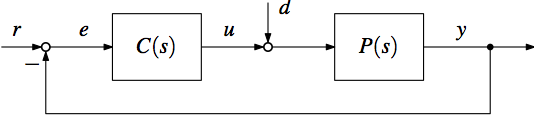

**Figura 1**: Sistema di controllo a retroazione unitaria dall'uscita.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Tracciare il diagramma di Bode della funzione di trasferimento d'anello $L(s)=C(s) P(s)$, e determinare poi la pulsazione di attraversamento $\omega_{gc}$ e il margine di fase $\varphi_m$.

*Soluzione*.

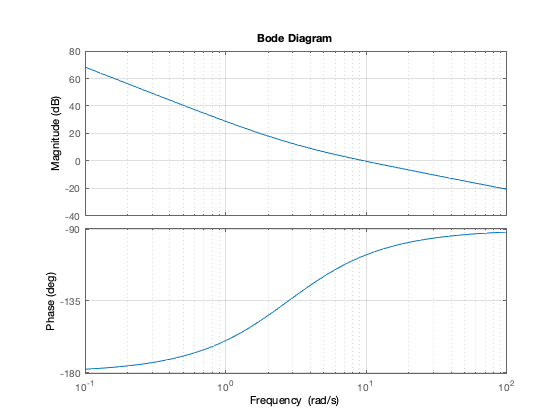

%   plant params
K = 2.8;
T = 0.3;

%   plant tf
sysP1 = tf(K, [T, 1, 0]);

%   controller params
kp = 6.2;
ki = 9.3;
kd = 1.0;

%   controller tf
sysC = tf([kd, kp, ki], [1, 0]);

%   loop tf 
sysL1 = sysP1*sysC;

%   loop tf - Bode plot
figure(1);
bode(sysL1);
hold on;
grid on;


%   phase margin and gain crossover freq
[~, phim, ~, wgc] = margin(sysL1);

Pulsazione di attraversamento $\omega_{gc}$:

wgc

wgc = 9.7487

Margine di fase $\varphi_m$:

phim

phim = 73.6943

2) Calcolare la funzione di trasferimento $T(s)$ del sistema in catena chiusa, da riferimento $r$ ad uscita $y$. Valutare successivamente la risposta $y$ del sistema in catena chiusa ad un riferimento di posizione $r$ a gradino unitario, e mostrarla poi in una figura Matlab. Si determinino inoltre tempo di assestamento al $5\%$ e sovraelongazione percentuale.

*Soluzione*.

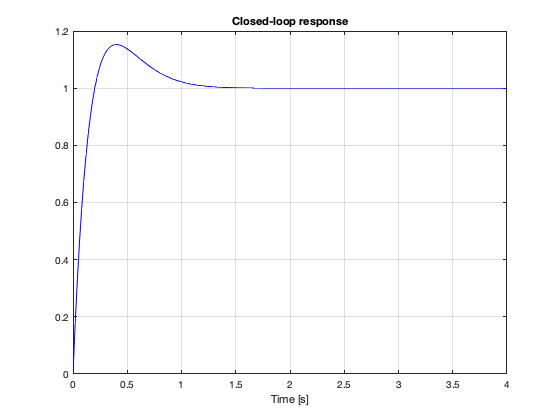

%   closed-loop tf
sysT1 = feedback(sysL1, 1);

%   step response
t = linspace(0, 4, 200);
y = step(sysT1, t);

%   plot step response
figure(2);
plot(t, y, 'b');
hold on;
grid on;
xlabel('Time [s]')
title('Closed-loop response');


%   step response parameters
info = stepinfo(sysT1, 'SettlingTimeThreshold', 0.05)

info = struct with fields:
        RiseTime: 0.1484
    SettlingTime: 0.8179
     SettlingMin: 0.9084
     SettlingMax: 1.1526
       Overshoot: 15.2553
      Undershoot: 0
            Peak: 1.1526
        PeakTime: 0.4011


3) A seguito dell'applicazione di un carico risonante all'albero di uscita del motore, si supponga che la funzione di trasferimento del motore si modifichi come segue:


$$P'(s) = P(s) G(s) \qquad \text{con} \qquad G(s) = \frac{\omega_n^2}{s^2 + 2 \delta\omega_n s + \omega_n^2}\quad\text{e}\quad \omega_n = 41.2\,\mathrm{rad/s}\,,\quad \delta = 0.05$$


Con riferimento alla nuova funzione di trasferimento $P'(s)$ del motore, si tracci il diagramma di Bode della funzione di trasferimento d'anello, sovrapponendolo a quello ottenuto al punto 1.

Si tracci poi il luogo delle radici del sistema, e si mostrino su tale luogo i poli del sistema in catena chiusa. Il sistema in catena chiusa è BIBO stabile ? Determinare il massimo guadagno $\bar{k}$ del controllore che assicura la stabilità del sistema in catena chiusa.

*Soluzione*.

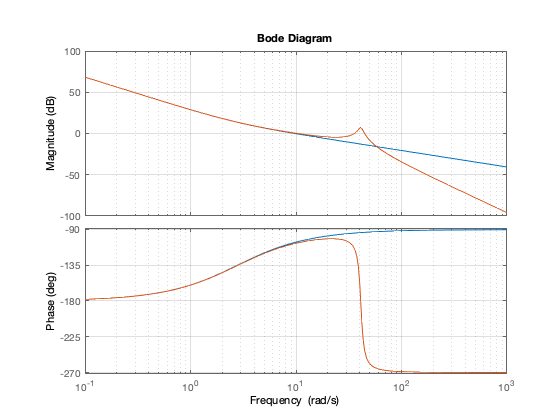

%   resonant mode params
wn = 41.2;
d = 0.05;

%   resonant mode tf
sysP2 = tf(wn^2, [1, 2*d*wn, wn^2]);

%   loop tf
sysL2 = sysL1*sysP2;

%   loop tf - Bode plot
figure(1);
bode(sysL2);

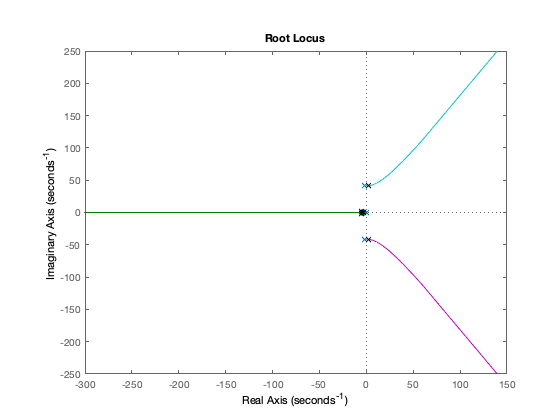

%   root locus
figure(3);
rlocus(sysL2);
hold on;

%   closed-loop poles
sysT2 = feedback(sysL2, 1);
p = pole(sysT2);
plot(p, 'kx');

Il controllore $C(s)$ non assicura la stabliità del sistema di controllo in caena chiusa. Il massimo valore di guadagno $\bar{k}$ che assicura la stabilità è pari a:

%   gain margin
Gm = margin(sysL2)

Gm = 0.4383

Ovviamente, con tale valore di guadagno, la banda di controllo (e.g. pulsazione di attraversamento) è ridotta, e quindi le prestazioni (in termini di tempo si salita/assestamento) sono inferiori rispetto al caso non risonante.

 4) Al fine di riutilzzare il controllore PID nelle condizioni con carico risonante, senza ridurre il guadagno per assicurare la stabilità dell'anello di controllo, si consideri di inserire in serie al controllore $C(s)$ un filtro notch del tipo:


$$N(s) = \frac{s^2 + 2\delta_z\omega_0\,s + \omega_0^2}{s^2 + 2\delta_p\omega_0\,s + \omega_0^2}\qquad \text{con}\qquad \delta_z = 0.1\,,\quad\delta_p = 0.9\,,\quad \omega_0 = \omega_n$$


in modo tale che la funzione di trasferimento del nuovo controllore diventi $C'(s) = C(s) N(s)$.

Con riferimento alla nuova funzione di trasferimento $C'(s)$ del controllore,  si tracci il diagramma di Bode della funzione di trasferimento d'anello, sovrapponendolo a quello ai punti 1 e 3.

Si tracci poi il luogo delle radici del sistema, e si mostrino su tale luogo i poli del sistema in catena chiusa. Il sistema in catena chiusa è BIBO stabile ? In caso affermativo, determinare la pulsazione di attraversamento $\omega_{gc}$ e il margine di fase $\varphi_m$ del sistema.

*Soluzione*.

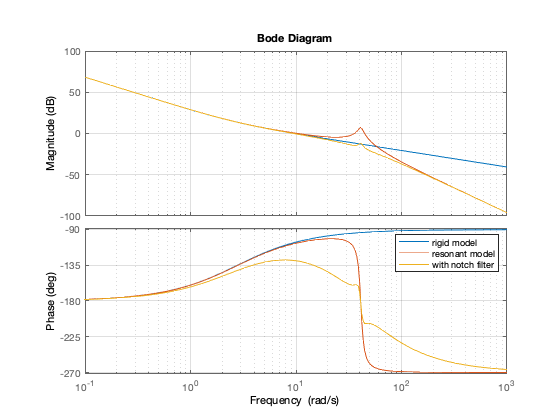

%   notch filter params
w0 = wn;
dz = 0.1;
dp = 0.9;

%   notch filter tf
sysN = tf([1, 2*dz*w0, w0^2], [1, 2*dp*w0, w0^2]);

%   loop tf
sysL3 = sysL2*sysN;

%   loop tf - Bode plot
figure(1);
bode(sysL3);
legend('rigid model', 'resonant model', 'with notch filter');

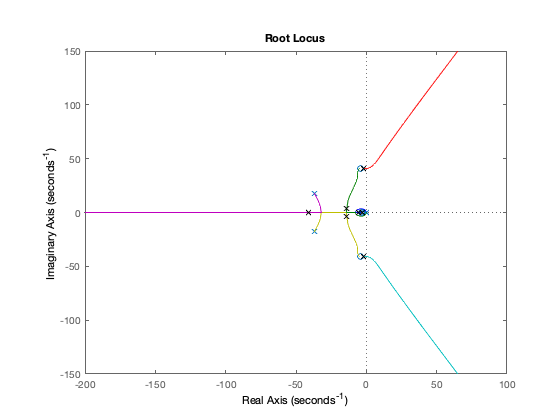

%   root locus
figure(4);
rlocus(sysL3);
hold on;

%   closed-loop poles
sysT3 = feedback(sysL3, 1);
p = pole(sysT3);
plot(p, 'kx');

Con l'introduzione del filtro notch, il controllore $C(s)$ è in grado di stabilizzare il sistema di controllo in catena chiusa.

%   phase margin and gain crossover freq
[~, phim, ~, wgc] = margin(sysL3);

Pulsazione di attraversamento $\omega_{gc}$:

wgc

wgc = 9.4636

Margine di fase $\varphi_m$:

phim

phim = 51.0415

La banda di controllo (pulsazione di attraversamento) è paragonabile a quella ottenuta nel caso di carico non risonante; tuttavia, il margine di fase è inferiore, e ciò comporterà una  risposta del sistema meno smorzata.

5) Nel caso in cui il sistema di controllo in catena chiusa con filtro notch sia BIBO stabile, valutare la risposta $y$  in catena chiusa ad un riferimento di posizione $r$ a gradino unitario, e mostrarla sovrapposta alla risposta ottenuta al punto 2 per il caso con carico non risonante.

*Soluzione*.

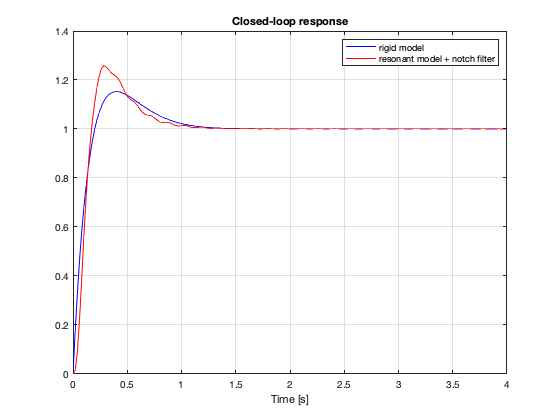

%   step response
y = step(sysT3, t);

%   plot step response
figure(2);
plot(t, y, 'r');
legend('rigid model', 'resonant model + notch filter');